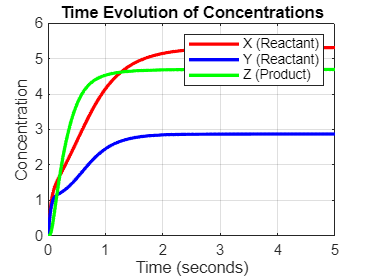

clc; clear; close all;

% Parameters
kx = 2; ky = 3; gamma = 2;
alpha = 10; beta = 2;
x0_e = 10; y0_e = 6;

% Initial conditions
x0 = 0; y0 = 0; z0 = 0;
t_end = 5; dt = 0.01;
t = 0:dt:t_end;

% Initialize variables
x = zeros(size(t)); y = zeros(size(t)); z = zeros(size(t));
x(1) = x0; y(1) = y0; z(1) = z0;

% Euler Method Simulation
for i = 1:length(t)-1
    k1 = max(0, alpha - beta * z(i)); % Enforce k1 >= 0
    dx = kx * (x0_e - x(i)) - k1 * x(i) * y(i);
    dy = ky * (y0_e - y(i)) - k1 * x(i) * y(i);
    dz = k1 * x(i) * y(i) - gamma * z(i);

    % Update values
    x(i+1) = x(i) + dt * dx;
    y(i+1) = y(i) + dt * dy;
    z(i+1) = z(i) + dt * dz;
end

% Plot results
figure;
plot(t, x, 'r', 'LineWidth', 2); hold on;
plot(t, y, 'b', 'LineWidth', 2);
plot(t, z, 'g', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Concentration');
legend('X (Reactant)', 'Y (Reactant)', 'Z (Product)');
title('Time Evolution of Concentrations');
grid on;